%% Output space-time grid

x = Grid1DUnifPrimal([0,1],101);
outputGrid = GridSpace1D(x);
outputTimes = linspace(0,1,51);

P = GridFunctionTimeSeries(outputGrid,outputTimes, ...

U =   GridFunctionTimeSeries with properties:

      grid: [1×1 GridSpace1D]
     times: [0 0.0200 0.0400 0.0600 0.0800 0.1000 0.1200 0.1400 0.1600 0.1800 0.2000 0.2200 0.2400 0.2600 0.2800 0.3000 0.3200 0.3400 0.3600 0.3800 0.4000 0.4200 0.4400 0.4600 0.4800 0.5000 0.5200 0.5400 0.5600 0.5800 0.6000 0.6200 … ] (1×51 double)
    values: [101×51 double]
         N: 101
        Nt: 51
       dim: 1


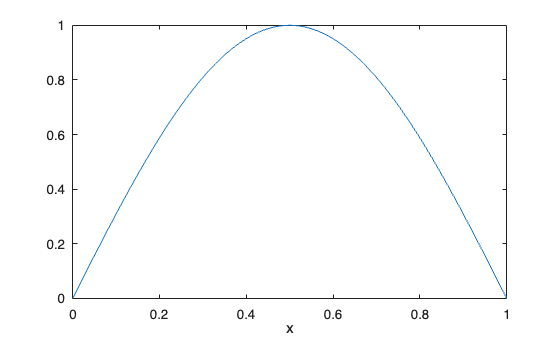

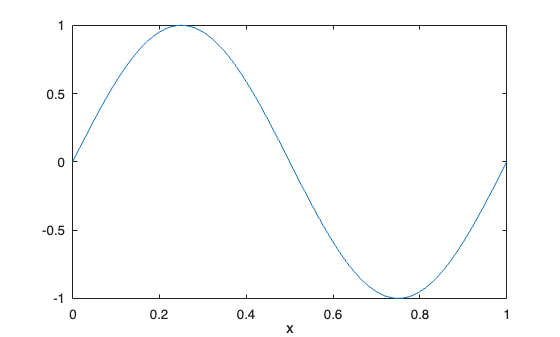

    Label="Pressure",Units="Pa", ...
    TimeLabel="Time",TimeUnits="s")

% Values stored in an array

pValues = sin(pi*x.pts);
P.setSnapshot(1,pValues);

% Values stored in a GridFunction
xComp = Grid1DUnifPrimal([0,1],401);
compGrid = GridSpace1D(xComp);

uComp = GridFunction(compGrid);
uComp.setValues(@(x) sin(2*pi*x));

% Automatically interpolates from compGrid to outputGrid
U.setSnapshot(2,uComp);

% Retrieve a snapshot and plot
u = U.snapshot(1);
u.plot();